# **Coefficient of Restitution of a Golf ball**

[Coefficient of restitution](https://en.wikipedia.org/wiki/Coefficient_of_restitution) - The ratio of the final (u) to initial (v) relative velocity between two objects after they collide.


$$C_r =\frac{\mathrm{Final}\;\mathrm{velocity}\;\mathrm{after}\;\mathrm{collision}\;\left(u\right)}{\mathrm{Initial}\;\mathrm{velocity}\;\mathrm{before}\;\mathrm{collision}\left(v\right)}$$


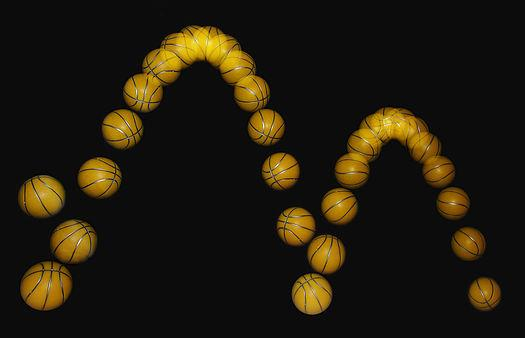

It normally ranges from 0 to 1 where 1 would be a perfectly elastic collision.

#### **Setup Parameters**

H_o = 10;
V_o = 25;
G = -9.81; %m/s^2
cr = 0.86;  % Coefficient of restitution

dt = 0.01;
T = 0:dt:45;
H = zeros(1, length(T)); %meters
V = zeros(1, length(T)); %m/s

H(1) = H_o;
V(1 : end) = V_o;

#### Simulate Trajectory

for i = 2:length(T) % Automatically change value of v
    V(i) = V(i-1) + G * dt; 
    H(i) = H(i-1) + V(i) * dt;
    
    %Bounce
    if (H(i) <= 0)
        V(i) = -V(i) * cr;
        H(i) = 0;
    end
end

#### Plot Path & Velocity

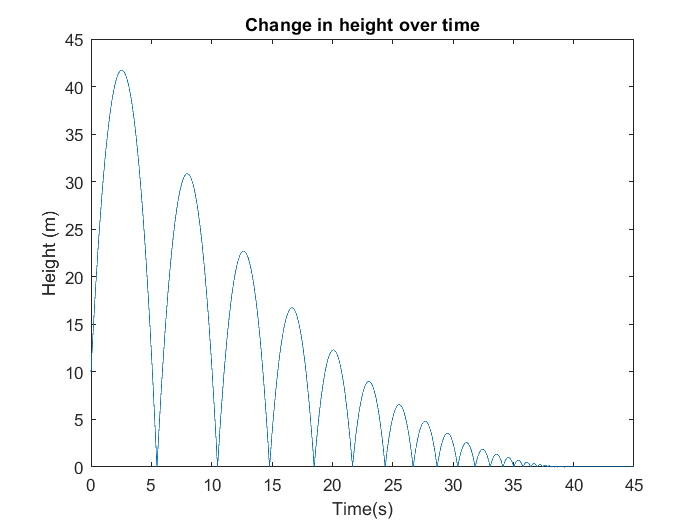

plot(T, H)
title('Change in height over time')
xlabel('Time(s)')
ylabel('Height (m)')

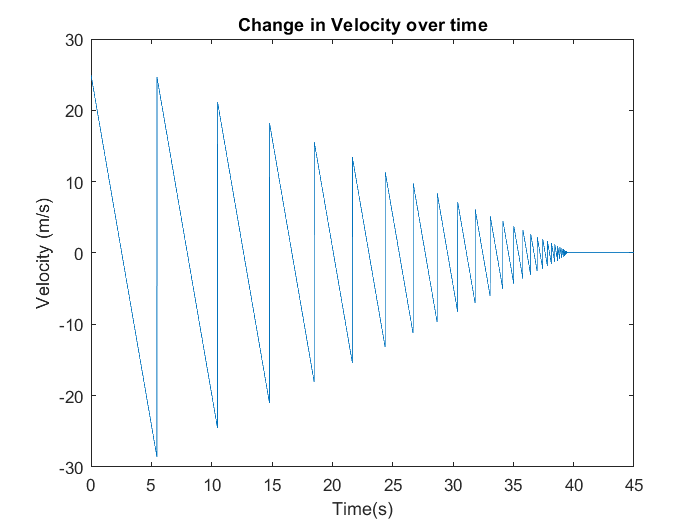

plot(T, V)
title('Change in Velocity over time')
xlabel('Time(s)')
ylabel('Velocity (m/s)')